# Eksamen 2021F løsning

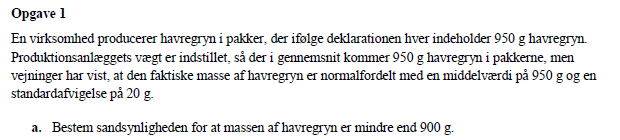

clc; clear;

% Normalfordelt med 
mu = 950;
stdafv = 20;

P_mindre_end_900g = normcdf(900, mu, stdafv)

P_mindre_end_900g = 0.0062

P_mellem_900g_og_1010g = normcdf(1010, mu, stdafv) - normcdf(900, mu, stdafv)

P_mellem_900g_og_1010g = 0.9924

Der skal standardiseres


$$z_{0.03} = \frac{x-\mu}{\sigma}$$


syms mu

z0 = norminv(0.03)

z0 = -1.8808


eq = z0 == (950 - mu)/stdafv;

mu = solve(eq, mu);
mu = vpa(mu,6)

$$mu = 987.616$$

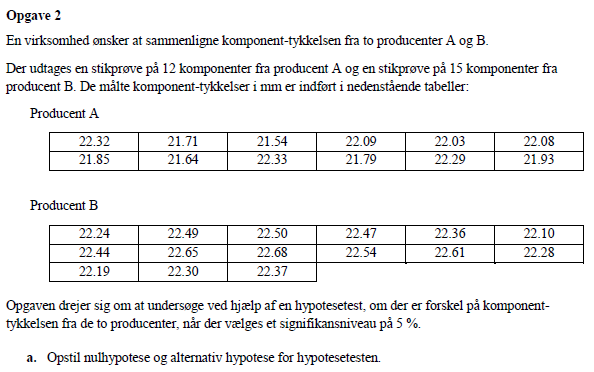

H0: tykkelse_A = tykkelse_B

Ha: tykkelse_A =/= tykkelse_B

Der er altså tale om en 2 sidet test på middelværdien

Det er ikke angivet at dataet et normalfordelt, og eftersom der er færre end 30 datapunkter, bruges der en t-fordeling til at gennemføre testen. 

Der bruges et script jeg selv har skrevet til udførsel af testen, der er inkluderet nederst i dokumentet, samt afleveret med eksamen.

Frihedsgradernes formel


$$\mathrm{df}=n_{1}+n_{2}-2$$

-----------------------------------------------------------------
Stikprøvemiddelværdiernes formel


$$\bar{y}=\frac{\Sigma \,y_{i}}{n}$$

-----------------------------------------------------------------
Stikprøvevariansernes formel


$$s=\frac{n\,\left(\Sigma \left({y_{i}}^{2}\right)-{\Sigma \left(y_{i}\right)}^{2}\right)}{n\,\left(n-1\right)}$$

-----------------------------------------------------------------
Pooled standardafvigelsens formel


$$s_{p}=\sqrt{\frac{\left(n_{1}-1\right)\,{s_{1}}^{2}+\left(n_{2}-1\right)\,{s_{2}}^{2}}{n_{1}+n_{2}-2}}$$

-----------------------------------------------------------------
t-værdiens formel


$$\frac{t_{\mathrm{df},\alpha }}{2}=-\mathrm{tinv}\,\frac{\alpha }{2}\,\mathrm{df}$$

-----------------------------------------------------------------
Teststørrelsens formel


$$t_{\mathrm{val}}=\frac{y_{\mathrm{bar1}}-y_{\mathrm{bar2}}}{s_{p}\,\sqrt{\frac{1}{n_{1}}\,\frac{1}{n_{2}}}}$$

-----------------------------------------------------------------
    Datanavne    Middelværdier    Spredning    standardafv.    Datapunkter
    _________    _____________    _________    ____________    ___________

    "Input 1"       21.967        0.072206       0.26871           12     
    "Input 2"       22.415         0.02947       0.17167           15     

    Frihedsgrader    Pooled varians    Pooled spredning    Nedre grænse    Øvre grænse    Teststatistik     p-værdi      h-værdi
    _____________    ______________    ________________    ____________    ___________    _____________<

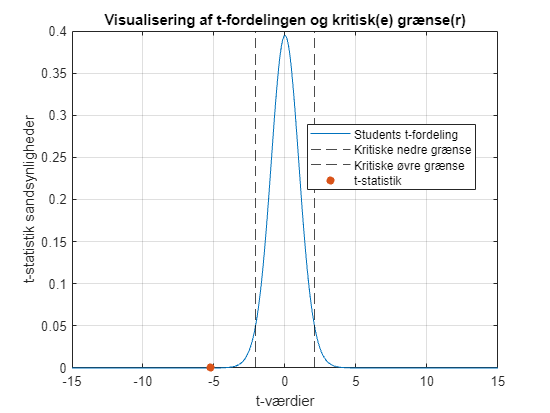

Da h = 1 forkastes nulhypotesen
Ydermere ses det også at t-værdien -5.2647 overstiger den kritiske grænse på -2.0595


clc; clear;
data = importdata("Data_M4STI1_2021F.xlsx").data;
prod_A = data(1:12,2);
prod_B = data(13:end,2);

OP = ttest2popMiddelInd(prod_A, prod_B,"both", 95,[]);

Det ses tydeligt, at på et 5% signifikansniveau, skal H0 hypotesen om at de har samme tykkelse, forkastes.

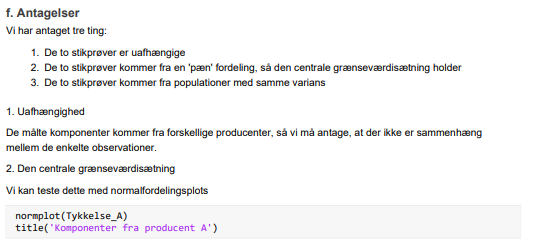

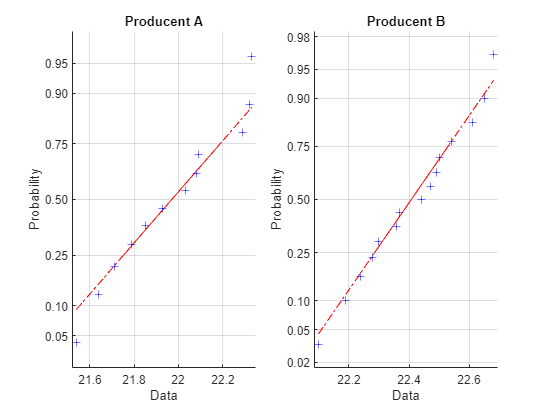


subplot(1,2,1)

normplot(prod_A)
title("Producent A")

subplot(1,2,2)

normplot(prod_B)
title("Producent B")

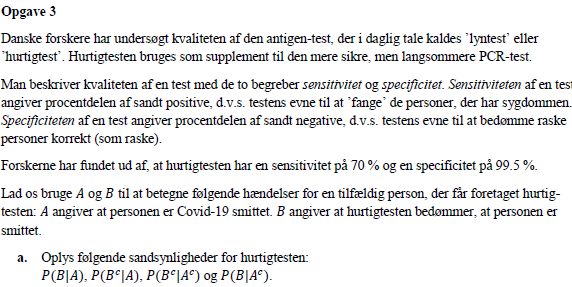

clc; clear;

% A angiver personen er smittet
% B angiver at hurtigtesten bedømmer at personen er smittet

A = 0.7

A = 0.7000

B = 0.995

B = 0.9950


P_B_givet_A = A

P_B_givet_A = 0.7000

P_Bc_givet_A = 1 - P_B_givet_A

P_Bc_givet_A = 0.3000

P_Bc_givet_Ac = B

P_Bc_givet_Ac = 0.9950

P_B_givet_Ac = 1 - B

P_B_givet_Ac = 0.0050

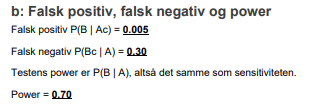

n = 1e4

n = 10000

smit = 0.2;

n_falsk_pos = n*(1-smit)*P_B_givet_Ac % 10 stk

n_falsk_pos = 40.0000


proc_falsk_pos = n_falsk_pos/(n*smit)

proc_falsk_pos = 0.0200



proc_falsk_neg = n*A*P_B_givet_A

proc_falsk_neg = 4900

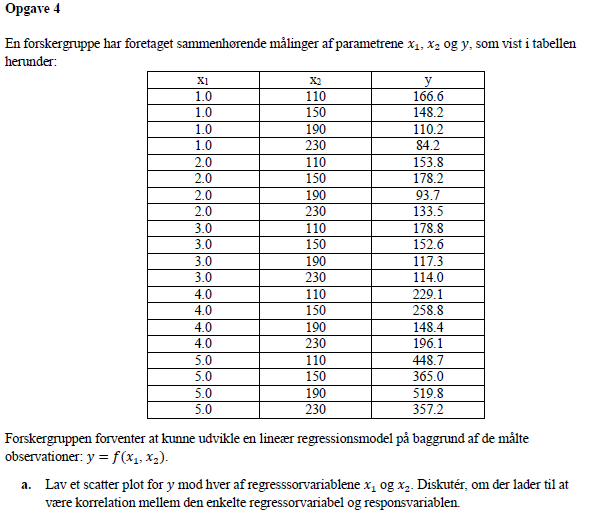

clc; clear;
data = importdata("Data_M4STI1_2021F.xlsx").data

data =     1.0000   22.3200       NaN       NaN    1.0000  110.0000  166.6000
    1.0000   21.7100       NaN       NaN    1.0000  150.0000  148.2000
    1.0000   21.5400       NaN       NaN    1.0000  190.0000  110.2000
    1.0000   22.0900       NaN       NaN    1.0000  230.0000   84.2000
    1.0000   22.0300       NaN       NaN    2.0000  110.0000  153.8000
    1.0000   22.0800       NaN       NaN    2.0000  150.0000  178.2000
    1.0000   21.8500       NaN       NaN    2.0000  190.0000   93.7000
    1.0000   21.6400       NaN       NaN    2.0000  230.0000  133.5000
    1.0000   22.3300       NaN       NaN    3.0000  110.0000  178.8000
    1.0000   21.7900       NaN       NaN    3.0000  150.0000  152.6000


data = data(1:20,5:end)

data =     1.0000  110.0000  166.6000
    1.0000  150.0000  148.2000
    1.0000  190.0000  110.2000
    1.0000  230.0000   84.2000
    2.0000  110.0000  153.8000
    2.0000  150.0000  178.2000
    2.0000  190.0000   93.7000
    2.0000  230.0000  133.5000
    3.0000  110.0000  178.8000
    3.0000  150.0000  152.6000
